load and pick data

close all;
clear;
clc;
load gaitdata.mat;
load actuatordata.mat;

%keep only sagittal hip data
TBL = removevars(gaitdata,{'aKsag', 'aAsag', 'mKsag_abs', 'mKsag_max', 'mKsag_min', 'mKsag_rel', 'mKsag_rms', 'pKsag_abs', 'pKsag_max', 'pKsag_min', 'pKsag_rel', 'mAsag_abs', 'mAsag_max', 'mAsag_min', 'mAsag_rel', 'mAsag_rms', 'pAsag_abs', 'pAsag_max', 'pAsag_min', 'pAsag_rel'});

% Join tables
pat = TBL{:,1};
nr= length(pat)

nr = 31


% zero crossing function
zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);

Numerical differentiation and low-pass filtering, assumption made on cadence

% Tgait = stride period
Tgait = 1.2%seconds

Tgait = 1.2000

%lowpass filter frequency
flp = 6

flp = 6

flp_load = 3

flp_load = 3

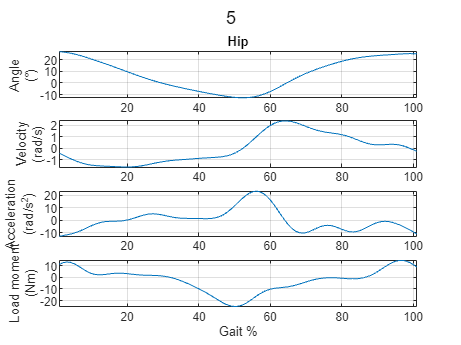


% select patient
id = 5;

H = diff_joints_v2_hiponly(TBL(id,:),Tgait,flp,flp_load); 

plotpat_hiponly(pat,H,id)

Evaluate motor feasability:

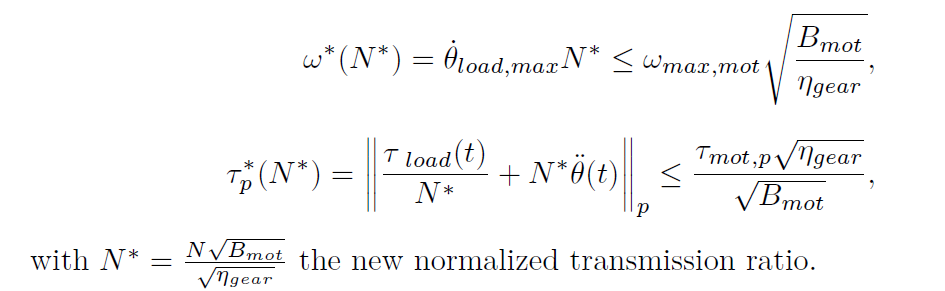

EQUATION N* is wrong !!! needs to be N*sqrt(Bmot*eta)

first equation needs to be normalised with sqrt(Bmot*eta)

Tload should be the sum of the exo-only actuation load and the desired assistance load moment

determining ex-only load has been omitted for this example. It should be derived via inverse dynamics of an exo model

% choose actuator and voltage
act_id = 6;
Voltage_used = 1*actuatordata.NOMINALVOLTAGEV(act_id);                      % is used to adapt speed proportionally
overload = 1.2    % overloading with additional cooling ?

overload = 1.2000

actuatordata

actuatordata = 9×18 table
         NAME          POWERW    NOMINALVOLTAGEV    NOLOADSPEEDrpm    NOMINALSPEEDrpm    NOMINALTORQUENm    PEAKTORQUENm    STALLTORQUENm    TORQUECFNmA    MAXCURRENTA    NOMINALCURRENTA    IDLECURRENTA      WINDTCs       INERTIAkgm    DIAMETERmm    LENGTHmm    WEIGHTkg         GEARINGS     
    _______________    ______    _______________    ______________    _______________    _______________    ____________    _____________    ___________    ___________    _______________  

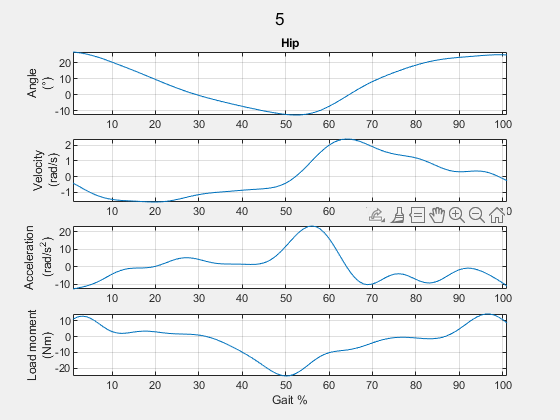

act_name = actuatordata.NAME{act_id};
Bmot = actuatordata.INERTIAkgm(act_id) ; % gearbox inertia is ignored
Tnom = actuatordata.NOMINALTORQUENm(act_id) * overload;
Tmax = actuatordata.PEAKTORQUENm(act_id);
Tstall= actuatordata.STALLTORQUENm(act_id);
wnom = 	actuatordata.NOMINALSPEEDrpm(act_id) * 2 * pi /60 * Voltage_used/actuatordata.NOMINALVOLTAGEV(act_id);
wnoload = actuatordata.NOLOADSPEEDrpm(act_id) * 2 * pi /60;

%gearing efficiency
eta =1;

%normalisation factors
f1 = sqrt(Bmot/eta);
f2 = sqrt(Bmot*eta);
wmot = wnom * f2;
Tmotmax = Tmax/f1;
Tmotrms = Tnom/f1;


assistfactor = 1.35;

set(gcf,'Visible','on')


% example: 
joint = H;
Npoints = 500;
Nrange = [0.01 3];

Motor is feasable if X markers are above their respective lines

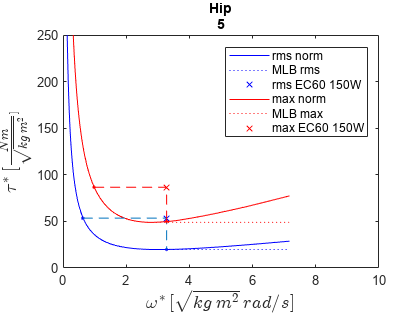


[N,omeganorm,momentnormRms, momentnormMax]=normratio_rms_max(joint,Nrange,Npoints,true,assistfactor);

figure
% rms curve
plot(omeganorm,momentnormRms,'b',omeganorm,cummin(momentnormRms),'b:',wmot,Tmotrms,'xb')
hold on
% get intersects
idxminrms = zci(momentnormRms-Tmotrms);
idxmax = zci(omeganorm-wmot);
its1 = [omeganorm(idxminrms(1)) Tmotrms];
its2 = [wmot, momentnormRms(idxmax(1))];
% max curve
plot(omeganorm,momentnormMax,'r',omeganorm,cummin(momentnormMax),'r:',wmot,Tmotmax,'xr')
% get intersects
idxminpk = zci(momentnormMax-Tmotmax);
its3 = [omeganorm(idxminpk(1)) Tmotmax];
its4 = [wmot, momentnormMax(idxmax(1))];
% plot intersects
plot([its1(1) its2(1)], [its1(2) its2(2)], '.b');
line([its1(1) wmot its2(1)],[its1(2), Tmotrms, its2(2)],'LineStyle','--');
plot([its3(1) its4(1)], [its3(2) its4(2)], '.r');
line([its3(1) wmot its4(1)],[its3(2), Tmotmax its4(2)],'LineStyle','--', 'Color', 'r');

hold off
legend('rms norm','MLB rms', ['rms ' act_name],'max norm','MLB max', ['max ' act_name]);
xlim([0 10]);
xlabel('$\omega^*\,[\sqrt{kg\,m^2}\,rad/s]$', "Interpreter","latex", "FontSize",14);
ylim([0 250]);
ylabel('$\tau^*\,[\frac{Nm}{\sqrt{kg\,m^2}}]$', "Interpreter","latex", "FontSize",14);

title([joint.name pat(id)]);

% set(gcf,'Visible','on')

cond1 = Tmotrms > momentnormRms;
cond2 = Tmotmax > momentnormMax;
cond3 = wmot > omeganorm;
[~,idmin] = min(momentnormRms);
cond4 = [true(idmin,1);false(Npoints-idmin,1)];
Nfeas = N(cond1&cond2&cond3); %all conditions
%Nfeas = N(cond1&cond3); %ignore peak condition
Nfeasrange = [min(Nfeas),min(Nfeas)/f2; max(Nfeas),max(Nfeas)/f2]

Nfeasrange =     0.4175   46.3839
    1.3702  152.2423


Noptimal = min(max(Nfeas),N(idmin))/f2

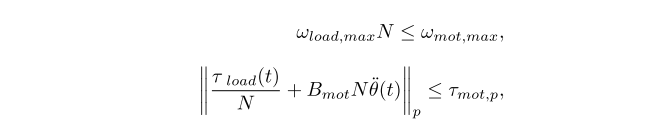

Pick gear ratio and evaluate margins

Nsel = 81

Nsel = 81


% speed margin
omega_load_max_atmot = max(abs(joint.ad))*Nsel;
moment_load_rms_atmot =  rms(-1*assistfactor*joint.m_abs./(Nsel*eta) + Bmot * Nsel * joint.add);
moment_load_max_atmot = max(abs(-1*assistfactor*joint.m_abs./(Nsel*eta) + Bmot * Nsel * joint.add));

speed_margin = (wnom - omega_load_max_atmot)/wnom

speed_margin = 0.4690

moment_margin_rms = (Tnom - moment_load_rms_atmot)/Tnom

moment_margin_rms = 0.5589

moment_margin_max = (Tmax - moment_load_max_atmot)/Tmax

moment_margin_max = 0.3453

Harmonic drive check

Tav=nthroot(sum(abs(joint.m_abs.^3.*joint.ad))/sum(abs(joint.ad)),3)

Tav = 9.9043

Trmsin = rms(-1*assistfactor*joint.m_abs)

Trmsin = 13.8886

Tmaxin = max(abs(-1*assistfactor*joint.m_abs))

Tmaxin = 33.7395


navout=mean(abs(joint.ad))*60/2/pi

navout = 10.5614

navin=navout*Nsel

navin = 855.4715

nmaxin = omega_load_max_atmot *60/2/pi

nmaxin = 1.8478e+03

SEA spring stiffness

The spring affects the motor torque and velocity profile

Efficiencies are omitted

minimize motor power or torque

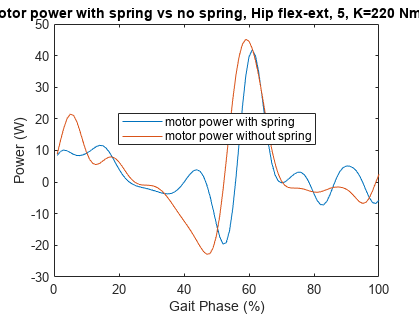

pspring_maxabs = zeros(1000,1);
mspring_rms = zeros(1000,1);
KS=linspace(1,1000,1000);

for idx=1:1000
    
    pspring_maxabs(idx) = max(abs(((-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*(joint.add+(-1)*joint.mdd*assistfactor/KS(idx))).*(joint.ad + (-1)*joint.md*assistfactor/KS(idx))));
    mspring_rms(idx) = rms(((-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*(joint.add+(-1)*joint.mdd*assistfactor/KS(idx))));
    
end

mnospring = (-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*(joint.add);                                %torque no spring
pnospring = mnospring.*(joint.ad);                                                                  %power no spring
     

[~,idpmin]=min(abs(pspring_maxabs));
[~,idmmin]=min(mspring_rms);

% spring rates that result in minimum power and moment rms
if KS(idpmin) ~= max(KS)
    KS_minPabsPeak = KS(idpmin);
end

if KS(idmmin) ~= max(KS)
    KS_minMrms = KS(idmmin);
end

% spring rates that result in equal power and moment rms as with no spring
% may not exist => try
try
    KS_breakevenPabsPeak=min(KS(zci(pspring_maxabs-max(abs(pnospring)))));
catch ME
end

try
    KS_breakevenMrms=min(KS(zci(mspring_rms-rms(mnospring))));
catch ME
end

%Select a spring constant
Ksel = 220;

% Altered gait profiles due to spring
joint.adsel = (joint.ad + (-1)*joint.md*assistfactor/Ksel);
joint.addsel = (joint.add+(-1)*joint.mdd*assistfactor/Ksel);
joint.msel = ((-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*joint.addsel);
joint.psel = joint.msel.*joint.adsel;

% Motor power plot, with and without spring
figure;
plot(joint.psel)
hold on
plot(pnospring)
legend({'motor power with spring','motor power without spring'},"Location","best");
xlim([0 100]);
xlabel('Gait Phase (%)')
ylabel('Power (W)')
title("Motor power with spring vs no spring, Hip flex-ext, " + pat(id) + ", K=" +string(Ksel) + " Nm/rad")
hold off

rms(joint.psel)

ans = 11.5020

rms(pnospring)

ans = 15.2916

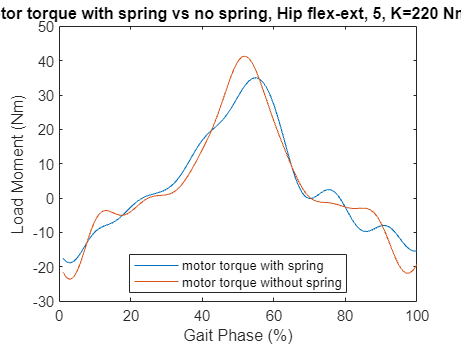


% Motor torque plot, with and without spring
plot(joint.msel);
hold on
plot(mnospring)
legend({'motor torque with spring','motor torque without spring'},"Location","best");
xlim([0 100]);
xlabel('Gait Phase (%)')
ylabel('Load Moment (Nm)')
title("Motor torque with spring vs no spring, Hip flex-ext, " + pat(id) + ", K=" +string(Ksel) + " Nm/rad")
hold off

rms(joint.msel)

ans = 15.4963

rms(mnospring)

ans = 17.1934


% Motor velocity plot, with and without spring
plot(joint.adsel)
hold on
plot(joint.ad)
legend({'motor speed with spring','motor speed without spring'},"Location","best");
rms(joint.adsel)

ans = 1.0540

rms(joint.ad)

ans = 1.2588

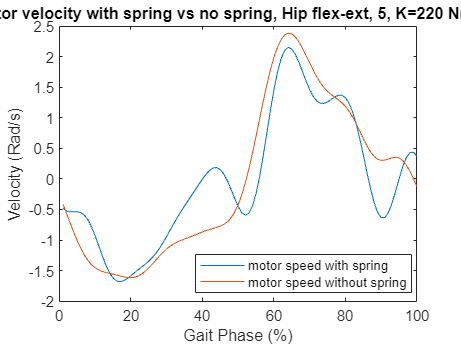

xlim([0 100]);
xlabel('Gait Phase (%)')
ylabel('Velocity (Rad/s)')
title("Motor velocity with spring vs no spring, Hip flex-ext, " + pat(id) + ", K=" +string(Ksel) + " Nm/rad")
hold off

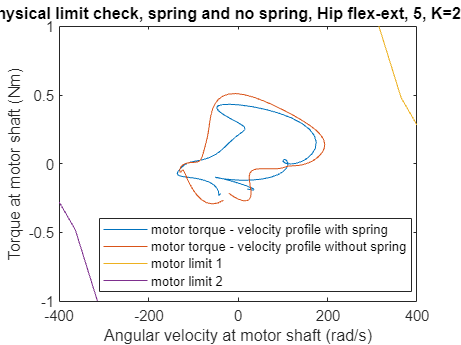


% Verify that profiles are withing motor physical limits due to back emf
plot(joint.adsel*Nsel,joint.msel/Nsel)
hold on
plot(joint.ad*Nsel,mnospring/Nsel)
vec_w= [0 wnom wnoload];
vec_T= [Tstall Tnom 0];
plot(vec_w,vec_T,-1*vec_w, -1*vec_T)
xlim([-400, 400]);
ylim([-1 1]);
legend({'motor torque - velocity profile with spring', 'motor torque - velocity profile without spring', 'motor limit 1', 'motor limit 2'}, "Location","best")
xlabel('Angular velocity at motor shaft (rad/s)')
ylabel('Torque at motor shaft (Nm)')
title("Motor physical limit check, spring and no spring, Hip flex-ext, " + pat(id) + ", K=" +string(Ksel) + " Nm/rad")

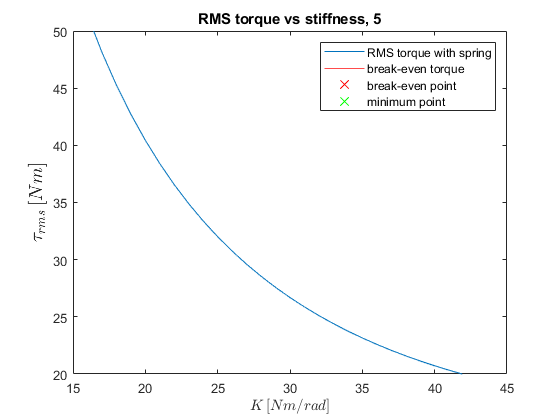


% Plot effect of stifness on rms motor torque
figure;
plot(KS,mspring_rms)
yline(rms(mnospring),'r', 'No Spring RMS');
ylim([20,50]);
xlabel('$K\,[Nm/rad]$', "Interpreter","latex")
ylabel('$\tau_{rms}\,[Nm]$', "Interpreter","latex","FontSize",14);
title("RMS torque vs stiffness, " + pat(id));
% add break-even and minimum marker
hold on
plot(KS_breakevenMrms,rms(mnospring),'xr','MarkerSize',10)
plot(KS_minMrms,mspring_rms(idmmin),'xg','MarkerSize',10)
legend('RMS torque with spring', 'break-even torque','break-even point',  'minimum point')
hold off
set(gcf,'Visible','on')

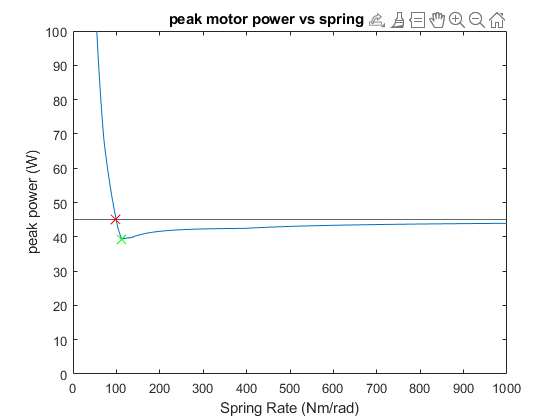


% Plot effect of stifness on peak motor power
figure;
plot(KS,pspring_maxabs)
yline(max(abs(pnospring)));
ylim([0,100]);
xlabel('Spring Rate (Nm/rad)')
ylabel('peak power (W)')
title("peak motor power vs spring rate, " + pat(id));
% add break-even and minimum marker
hold on
try
plot(KS_breakevenPabsPeak,max(abs(pnospring)),'xr','MarkerSize',10)
plot(KS_minPabsPeak,pspring_maxabs(idpmin),'xg','MarkerSize',10)
catch ME
end
hold off
set(gcf,'Visible','on')